# Rattlesnake Analyses

This script is a reproduction of the analysis workfllow described in [Forsthofer, Michael, et al. "Frequency modulation of rattlesnake acoustic display affects acoustic distance perception in humans." *Current Biology* 31.19 (2021): 4367-4372.](https://doi.org/10.1016/j.cub.2021.07.018) 

## **Video Abstract**

A video abstract of the project can be found on [cell.com](https://www.cell.com/current-biology/fulltext/S0960-9822(21)00973-8)

## **Project Summary**

The estimation of one’s distance to a potential threat is essential for any animal’s survival. Rattlesnakes inform about their presence by generating acoustic broadband rattling sounds. 1 Rattlesnakes generate their acoustic signals by clashing a series of keratinous segments onto each other, which are located at the tip of their tails. 1 ,  2 ,  3 Each tail shake results in a broadband sound pulse that merges into a continuous acoustic signal with fast-repeating tail shakes. This acoustic display is readily recognized by other animals 4 ,5 and serves as an aposematic threat and warning display, likely to avoid being preyed upon. 1 ,6 The spectral properties of the rattling sound 1 ,3 and its dependence on the morphology and size of the rattle have been investigated for decades 7 ,  8 ,  9 and carry relevant information for different receivers, including ground squirrels that encounter rattlesnakes regularly. 10 ,11 Combining visual looming stimuli with acoustic measurements, we show that rattlesnakes increase their rattling rate (up to about 40 Hz) with decreasing distance of a potential threat, reminiscent of the acoustic signals of sensors while parking a car. Rattlesnakes then abruptly switch to a higher and less variable rate of 60–100 Hz. In a virtual reality experiment, we show that this behavior systematically affects distance judgments by humans: the abrupt switch in rattling rate generates a sudden, strong percept of decreased distance which, together with the low-frequency rattling, acts as a remarkable interspecies communication signal.

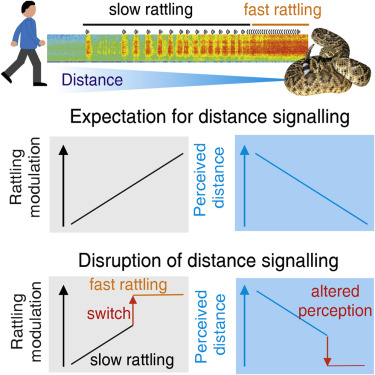

## Accumulate and Sort Subject Data

clearvars
addpath("experimentData")
subjectIDs = ["hz", "ls", "uo", "fn", "ql", "at", "cf", "sd", "qr", "op", "te"]';
subjectAges = [30 25 22 20 21 23 21 36 22 22 21]';
meanAge = mean(subjectAges)

meanAge = 23.9091

subjectSexes = categorical(["f", "f", "m", "f", "f", "m", "f", "m", "f", "f", "f"]');
T = table(subjectIDs, subjectAges, subjectSexes, 'VariableNames', {'ID', 'Age', 'Sex'})

T = 11×3 table
     ID     Age    Sex
    ____    ___    ___

    "hz"    30      f 
    "ls"    25      f 
    "uo"    22      m 
    "fn"    20      f 
    "ql"    21      f 
    "at"    23      m 
    "cf"    21      f 
    "sd"    36      m 
    "qr"    22      f 
    "op"    22      f 
    "te"    21      f 


Preallocate cells for storing all subject data

distance_data = cell(numel(subjectIDs),1);
contact_data = cell(numel(subjectIDs),1);
dataCollectDir = "experimentData";
for n = 1:numel(subjectIDs)
   distance_data{n} = readtable(dataCollectDir + filesep + "s_" + T.ID(n) + filesep + "ssn_02/results.csv");
   contact_data{n} = readtable(dataCollectDir + filesep + "s_" + T.ID(n) + filesep + "ssn_03/results.csv");
end

Add these data to table T

T = addvars(T, distance_data);
T = addvars(T, contact_data);
disp(T)

     ID     Age    Sex    distance_data     contact_data 
    ____    ___    ___    ______________    _____________

    "hz"    30      f     {288×10 table}    {192×9 table}
    "ls"    25      f     {288×10 table}    {192×9 table}
    "uo"    22      m     {288×10 table}    {240×9 table}
    "fn"    20      f     {288×10 table}    {240×9 table}
    "ql"    21      f     {288×10 table}    {240×9 table}
    "at"    23      m     {288×10 table}    {240×9 table}
    "cf"    21      f     {288×10 table}    {240×9 table}
    "sd"    36      m     {288×10 table}    {240×9 table}
    "qr"    22      f     {288×10 table}    {240×9 table}
    "op"    22      f     {288×10 table}    {240×9 table}
    "te"    21      f     {288×10 table}    {240×9 table}



allDistanceData = vertcat(distance_data{:});
distanceSubjectTrials = arrayfun(@(x) size(distance_data{x},1), 1:size(distance_data,1));
IDs_allDistanceData = arrayfun(@(n) categorical(ones(1,distanceSubjectTrials(n)), [1], ...
    subjectIDs{n})', 1:numel(subjectIDs), 'UniformOutput', false);
IDs_allDistanceData = vertcat(IDs_allDistanceData{:}); 
allDistanceData = addvars(allDistanceData, IDs_allDistanceData, 'NewVariableNames',{'subjectID'}); % add subject ID info to allDistanceData

allContactData = vertcat(contact_data{:});
contactSubjectTrials = arrayfun(@(x) size(contact_data{x},1), 1:size(contact_data,1));
IDs_allContactData = arrayfun(@(n) categorical(ones(1,contactSubjectTrials(n)), [1], ...
    subjectIDs{n})', 1:numel(subjectIDs), 'UniformOutput', false);
IDs_allContactData = vertcat(IDs_allContactData{:}); 
allContactData = addvars(allContactData, IDs_allContactData, 'NewVariableNames',{'subjectID'}); % add subject ID info to allContactData

approach_times = unique(allDistanceData.approach_time)

approach_times =     2.0000
    2.5000
    4.5000


distances = unique(allDistanceData.distance)

distances =     1.0000
    1.4142
    2.0000
    2.8284
    4.0000
    5.6569


start_distances = unique(allContactData.start_distance)

start_distances =     1.4142
    2.0000
    2.8284
    4.0000
    5.6569
    8.0000


## Response Histogram

Subjects were asked to indicate when they estimate their distance from the rattle snake as equalling 1 m. x-axis: distance [m] to the "virtual rattle snake"

color code: (probably) -- orange (mod + freq shift) & blue (const freq) [see last image produced in script ]

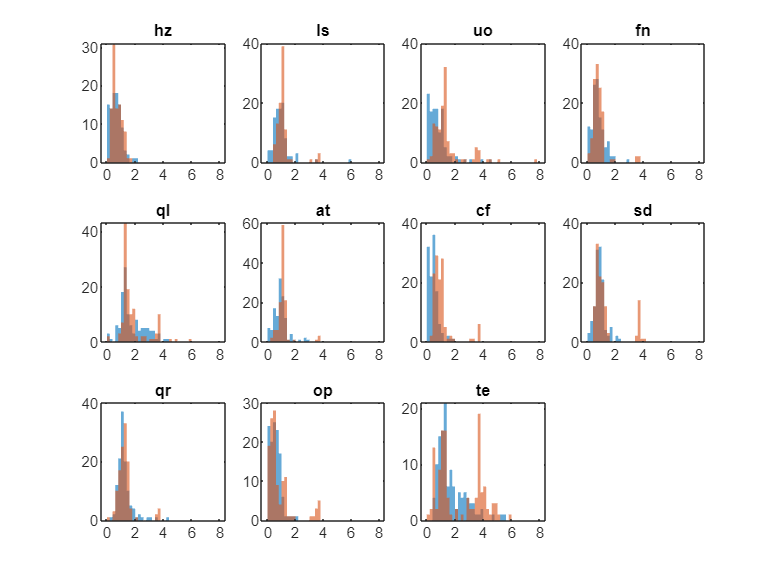

nBins = 41;
histEdges = linspace(0,8,nBins);
tiledlayout(3,4), nexttile

GroupedMedians = cell(numel(T.ID),1); % preallocate
for n = 1:numel(T.ID)
    subject = T.ID(n);
    data = T.contact_data{n};
    
    % get info for histograms
    constInds = find(strcmp(data.condition, 'rattle_const'));
    subjectConstResps = data.response(constInds);
    modInds = find(strcmp(data.condition, 'rattle_mod'));
    subjectModResps = data.response(modInds);
    histogram(subjectConstResps, histEdges, Edgecolor="none")
    hold on
    title(T.ID(n))
    histogram(subjectModResps, histEdges, Edgecolor="none")
    hold off
    if n < numel(T.ID), nexttile, end

    % calculate medains for subject & condition
    groupVals = groupsummary(data, {'condition', 'start_distance'}, 'median', 'response');
    subjectIDs = categorical(ones(1,12), 1, subject)';
    groupVals = addvars(groupVals, subjectIDs);
    GroupedMedians{n,1} = groupVals;
end

## Comparison of Medians 

A two-sample Kolmogorov-Smirnov test is used to determine if data for constant frequency responses and data for moulated frequency responses are from the same continuous distribution.

N = nnz(allContactData.start_distance<=4 & allContactData.condition=="rattle_mod" & allContactData.response == 0)

N = 26

constKSData = allContactData.response(find(strcmp(allContactData.condition,'rattle_const') & allContactData.start_distance <= 4));
modKSData = allContactData.response(find(strcmp(allContactData.condition,'rattle_mod') & allContactData.start_distance <= 4));
[h,p] = kstest2(constKSData,modKSData)

h = logical
   1


p = 1.4654e-12

The null hypothesis could be rejected (at significance level p). 

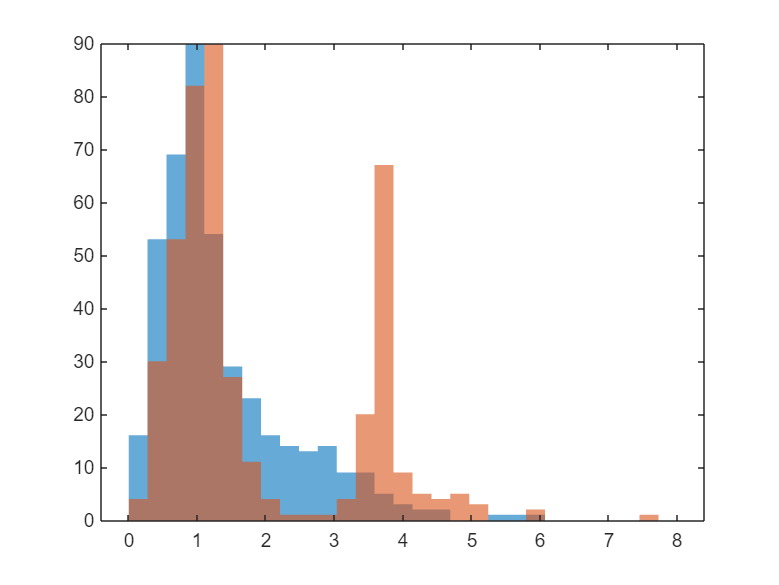

constHist = find(strcmp(allContactData.condition,'rattle_const') & allContactData.start_distance > 4);
modHist = find(strcmp(allContactData.condition,'rattle_mod') & allContactData.start_distance > 4);
nBins = 30;
histEdges = linspace(0,8,nBins);

figure,
histogram(allContactData.response(constHist), histEdges, EdgeColor="none"), hold on
histogram(allContactData.response(modHist), histEdges, EdgeColor="none"), hold off

In this section of the script a Mann-Whitney U-test is employed. This test tests the null hypothesis that two sets of data are samples from continuous distributions with equal medians. 

Data tested includes medians of the distance where subjects perceived themselves as 1 meter away from the snake (grouped by condition, experimental subject and starting distance).

**Mann-Whitney U-test**

median_results = vertcat(GroupedMedians{:});
const_results = median_results(strcmp(median_results.condition,"rattle_const"),:);
mod_results = median_results(strcmp(median_results.condition,"rattle_mod"),:);

constLarger4 = const_results(const_results.start_distance>4,:);
head(constLarger4) % preview top of table

ans = 8×5 table
       condition        start_distance    GroupCount    median_response    subjectIDs
    ________________    ______________    __________    _______________    __________

    {'rattle_const'}        5.6569            16            0.62794            hz    
    {'rattle_const'}             8            16            0.73209            hz    
    {'rattle_const'}        5.6569            16              1.008            ls    
    {'rattle_const'}             8            16             1.0903            ls    
    {'rattle_const'}        5.6569            20             1.0465            uo    
    {'rattle_const'}             8            20             1.0206            uo    
    {'rattle_const'}        5.6569            20             1.0365            fn    
    {'rattle_const'}             8     

modLarger4 = mod_results(mod_results.start_distance>4,:);
head(modLarger4) % preview top of table

ans = 8×5 table
      condition       start_distance    GroupCount    median_response    subjectIDs
    ______________    ______________    __________    _______________    __________

    {'rattle_mod'}        5.6569            16            0.73934            hz    
    {'rattle_mod'}             8            16             1.0014            hz    
    {'rattle_mod'}        5.6569            16             1.1733            ls    
    {'rattle_mod'}             8            16             1.0698            ls    
    {'rattle_mod'}        5.6569            20             1.2605            uo    
    {'rattle_mod'}             8            20             1.3583            uo    
    {'rattle_mod'}        5.6569            20            0.72086            fn    
    {'rattle_mod'}             8            20           

[pMWU_larger, hMWU_larger]=ranksum(constLarger4.median_response,modLarger4.median_response)

pMWU_larger = 0.1771

hMWU_larger = logical
   0


`hMWU_larger` is 0, i.e. it indicates a failure of the test to reject the null hypothesis (tested medians are samples from continuous distributions with equal median) for starting distances over 4 meters. 

constSmaller4 = const_results(const_results.start_distance<=4,:);
head(constSmaller4) % preview top of table

ans = 8×5 table
       condition        start_distance    GroupCount    median_response    subjectIDs
    ________________    ______________    __________    _______________    __________

    {'rattle_const'}        1.4142            16            0.57309            hz    
    {'rattle_const'}             2            16            0.51282            hz    
    {'rattle_const'}        2.8284            16             0.4656            hz    
    {'rattle_const'}             4            16            0.56282            hz    
    {'rattle_const'}        1.4142            16            0.53317            ls    
    {'rattle_const'}             2            16            0.73201            ls    
    {'rattle_const'}        2.8284            16            0.88257            ls    
    {'rattle_const'}             4     

modSmaller4 = mod_results(mod_results.start_distance<=4,:);
head(modSmaller4)

ans = 8×5 table
      condition       start_distance    GroupCount    median_response    subjectIDs
    ______________    ______________    __________    _______________    __________

    {'rattle_mod'}        1.4142            16            0.62489            hz    
    {'rattle_mod'}             2            16            0.56927            hz    
    {'rattle_mod'}        2.8284            16            0.54782            hz    
    {'rattle_mod'}             4            16            0.76186            hz    
    {'rattle_mod'}        1.4142            16            0.91513            ls    
    {'rattle_mod'}             2            16            0.89346            ls    
    {'rattle_mod'}        2.8284            16             1.0292            ls    
    {'rattle_mod'}             4            16           

[pMWU_smaller, hMWU_smaller]=ranksum(constSmaller4.median_response,modSmaller4.median_response, tail="left")

pMWU_smaller = 0.0131

hMWU_smaller = logical
   1


`hMWU_larger` is 0, i.e. it indicates that the null hypothesis (tested medians are samples from continuous distributions with equal median) could be rejected (for starting distances over 4 meters). 

## Per-subject, per-start-difference overshoot rates

gr = allContactData;
overshoot = zeros(size(allContactData,1),1);
overshoot(allContactData.response == 0) = 1;
gr = addvars(gr, overshoot);
gr = groupsummary(gr, {'subjectID', 'start_distance' , 'condition'}, 'nnz', 'overshoot');
nnz_no_overshoot = gr.GroupCount-gr.nnz_overshoot;
gr = addvars(gr, nnz_no_overshoot, 'NewVariableNames', 'nnz_no_overshoot');
head(gr)

ans = 8×6 table
    subjectID    start_distance       condition        GroupCount    nnz_overshoot    nnz_no_overshoot
    _________    ______________    ________________    __________    _____________    ________________

       hz            1.4142        {'rattle_const'}        16              4                 12       
       hz            1.4142        {'rattle_mod'  }        16              0                 16       
       hz                 2        {'rattle_const'}        16              2                 14       
       hz                 2        {'rattle_mod'  }        16              0                 16       
       hz            2.8284        {'rattle_const'}        16              4                 12       
       hz            2.8284        {'rattle_mod'  }       

sum_gr = groupsummary(gr, {'start_distance','condition'},'sum',{'nnz_overshoot','nnz_no_overshoot'})

sum_gr = 12×5 table
    start_distance       condition        GroupCount    sum_nnz_overshoot    sum_nnz_no_overshoot
    ______________    ________________    __________    _________________    ____________________

        1.4142        {'rattle_const'}        11               44                    168         
        1.4142        {'rattle_mod'  }        11               11                    201         
             2        {'rattle_const'}        11               35                    177         
             2        {'rattle_mod'  }        11                4                    208         
        2.8284        {'rattle_const'}        11               16                    196         
        2.8284        {'rattle_mod'  }        11                8                    204         
             4        {'r

p_sum = NaN(numel(start_distances),1);
for n = 1:numel(start_distances)
    fisherMat = sum_gr(sum_gr.start_distance == start_distances(n),4:5);
    [~,p_sum(n),~] = fishertest(fisherMat);
end

disp([start_distances, p_sum])

    1.4142    0.0000
    2.0000    0.0000
    2.8284    0.1399
    4.0000    0.0064
    5.6569    0.0301
    8.0000    0.1219



subjectIDs = unique(gr.subjectID);
FisherSubject = table('Size', [numel(start_distances)*numel(subjectIDs),3],...
    'VariableTypes', {'string', 'double','double'},...
    'VariableNames', {'subjectID', 'start_distance', 'pFisher'});
hc = 1;
for n = 1:numel(subjectIDs)
    for m = 1:numel(start_distances)
        FisherSubject.subjectID(hc) = subjectIDs(n);
        FisherSubject.start_distance(hc) = start_distances(m);
        fisherMat = gr(gr.start_distance == start_distances(m) & gr.subjectID == subjectIDs(n),5:6);
        [~,FisherSubject.pFisher(hc),~] = fishertest(fisherMat);
        hc = hc + 1;
    end
end
disp(sortrows(FisherSubject))

    subjectID    start_distance     pFisher  
    _________    ______________    __________

      "at"           1.4142          0.047124
      "at"                2                 1
      "at"           2.8284                 1
      "at"                4                 1
      "at"           5.6569                 1
      "at"                8                 1
      "cf"           1.4142          0.047124
      "cf"                2        1.2884e-05
      "cf"           2.8284          0.047124
      "cf"                4           0.10603
      "cf"           5.6569                 1
      "cf"                8           0.10603
      "fn"           1.4142           0.23512
      "fn"                2           0.34165
      "fn"           2.8284                 1
      "fn"                4           0.48718
      "fn"           5.6569                 1
      "fn"             

 Contingency table test on overshoot information 

long_short_gr = sum_gr;
startDistLabel((long_short_gr.start_distance<=4),1) = "short";
startDistLabel((long_short_gr.start_distance>4),1) = "long";
long_short_gr.start_distance = startDistLabel

long_short_gr = 12×5 table
    start_distance       condition        GroupCount    sum_nnz_overshoot    sum_nnz_no_overshoot
    ______________    ________________    __________    _________________    ____________________

       "short"        {'rattle_const'}        11               44                    168         
       "short"        {'rattle_mod'  }        11               11                    201         
       "short"        {'rattle_const'}        11               35                    177         
       "short"        {'rattle_mod'  }        11                4                    208         
       "short"        {'rattle_const'}        11               16                    196         
       "short"        {'rattle_mod'  }        11                8                    204         
       "short"    

long_short_gr = groupsummary(long_short_gr, {'start_distance', 'condition'},'sum',{'sum_nnz_overshoot','sum_nnz_no_overshoot'})

long_short_gr = 4×5 table
    start_distance       condition        GroupCount    sum_sum_nnz_overshoot    sum_sum_nnz_no_overshoot
    ______________    ________________    __________    _____________________    ________________________

       "long"         {'rattle_const'}        2                   12                       412           
       "long"         {'rattle_mod'  }        2                    1                       423           
       "short"        {'rattle_const'}        4                  110                       738           
       "short"        {'rattle_mod'  }        4                   26                       822           


Generates a table containing numbes of overshoots (=no estimate of reaching 1m distance to the snake) for long and short trials for constant and modulated rattling. 

fisherMatShort = long_short_gr(long_short_gr.start_distance == "short", 4:5);
fisherMatLong = long_short_gr(long_short_gr.start_distance == "long", 4:5)

fisherMatLong = 2×2 table
    sum_sum_nnz_overshoot    sum_sum_nnz_no_overshoot
    _____________________    ________________________

             12                        412           
              1                        423           


Tests for the null hypothesis that there are no nonrandom associations between miss trials in modulated and nonmodulated rattling.

[~,p,~] = fishertest(fisherMatShort)

p = 1.7982e-14

[~,plong,~] = fishertest(fisherMatLong)

plong = 0.0032

In both paradigms, the null hypothesis is rejected 

## Per-subject, per-start-difference scatter plots

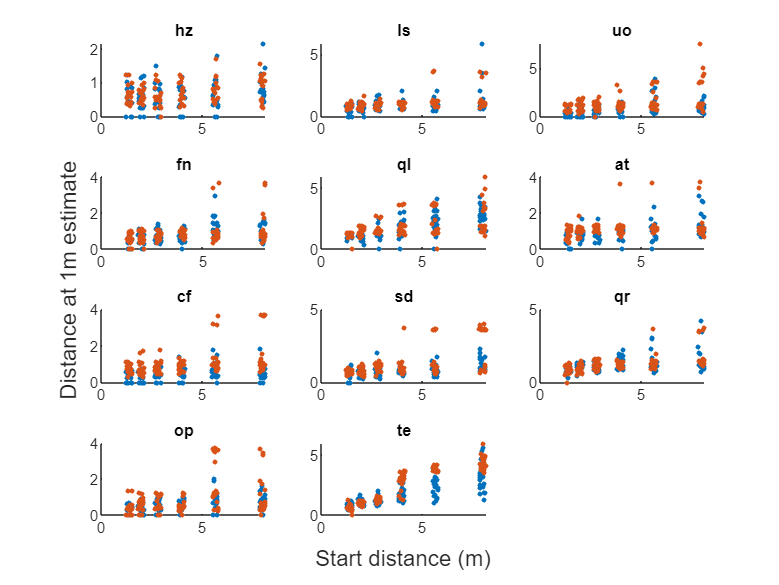

th=tiledlayout(4,3);
for n = 1:numel(T.ID)
    nexttile
    subject = T.ID(n);
    contactData = T.contact_data{n};
    xConst = contactData.start_distance(strcmp(contactData.condition,'rattle_const'));
    xConst = xConst + .3*rand(numel(xConst),1) - .15; % add/subtract number in the range +/- .15 for better visuals
    yConst = contactData.response(strcmp(contactData.condition,'rattle_const'));
    scatter(xConst,yConst,7,'filled')
    hold on
    xMod = contactData.start_distance(strcmp(contactData.condition,'rattle_mod'));
    xMod = xMod + .3*rand(numel(xMod),1) - .15; % add/subtract number in the range +/- .15 for better visuals
    yMod = contactData.response(strcmp(contactData.condition,'rattle_mod'));
    scatter(xMod,yMod,7,'filled')
    title(subject)
    hold off
end
    xlabel(th,'Start distance (m)')
    ylabel(th,'Distance at 1m estimate')

## Per-subject, per-start-distance difference pairs

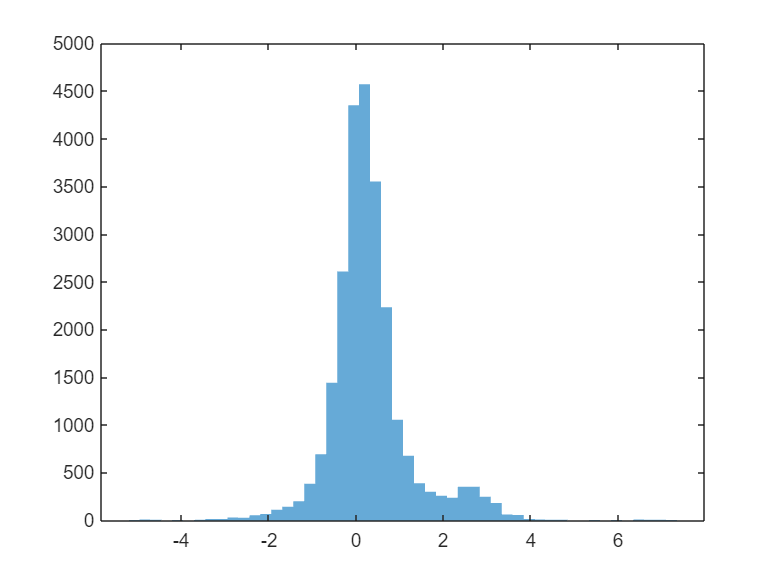

result_dfs = table('Size', [numel(T.ID)*numel(start_distances),3], 'VariableTypes', {'string', 'double','cell'}, 'VariableNames',...
{'ID', 'startDistance', 'modConstDifference'});
hc = 1;
for n = 1:numel(T.ID)
    data = contact_data{n};
    for sd = 1:numel(start_distances)
        start_distance = start_distances(sd);
        const_responses = data.response(find(strcmp(data.condition,'rattle_const') & data.start_distance == start_distance));
        mod_responses = data.response(find(strcmp(data.condition,'rattle_mod') & data.start_distance == start_distance));
        differences = mod_responses - const_responses'; 
        numel(differences);
        result_dfs.ID(hc) = T.ID{n};
        result_dfs.startDistance(hc) = start_distance;
        result_dfs.modConstDifference{hc} = reshape(differences,numel(differences), 1);
        hc = hc + 1;
    end
end
diff_df=vertcat(result_dfs.modConstDifference{:});
figure, histogram(diff_df, 50, EdgeColor="none")

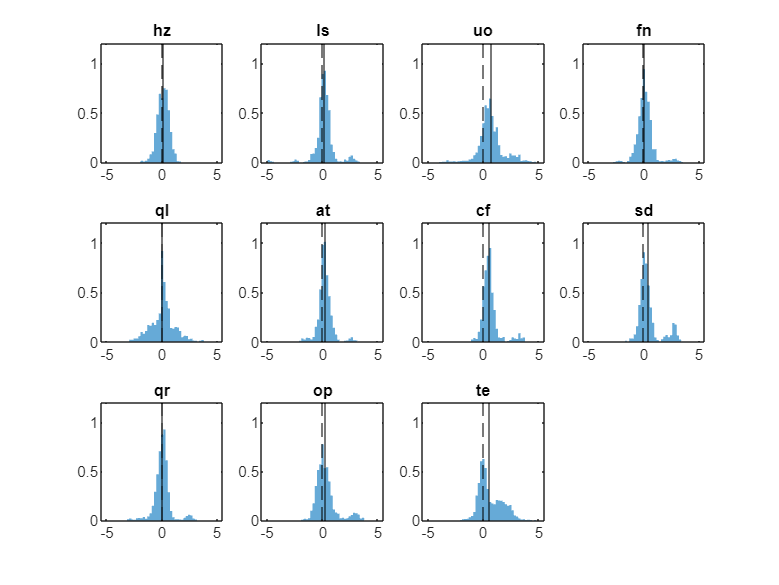

figure, tiledlayout(3,4)
for n = 1:numel(T.ID)
    nexttile
    subject = T.ID(n);
    df = vertcat(result_dfs.modConstDifference{result_dfs.ID == subject});
    histogram(df, linspace(-5,5,50),Normalization="pdf",EdgeColor="none"); hold on
    xline(0, 'k--')
    xline(mean(df), 'k-')
    title(subject)
    ylim([0 1.2])
    hold off
end

## Per-subject, per-start-distance mean differences

grMeanDiffs = groupsummary(allContactData, {'condition', 'start_distance','subjectID'}, 'mean', 'response');
grMeanDiffs.condition = categorical(grMeanDiffs.condition);
disp(grMeanDiffs)

     condition      start_distance    subjectID    GroupCount    mean_response
    ____________    ______________    _________    __________    _____________

    rattle_const        1.4142           hz            16           0.53614   
    rattle_const        1.4142           ls            16           0.52715   
    rattle_const        1.4142           uo            20           0.33447   
    rattle_const        1.4142           fn            20           0.39461   
    rattle_const        1.4142           ql            20            1.1896   
    rattle_const        1.4142           at            20           0.47958   
    rattle_const        1.4142           cf            20           0.41231   
    rattle_const        1.4142           sd            20           0.64984   
    rattle_const        1.4142         

grMeanDiffsConst = grMeanDiffs(grMeanDiffs.condition == 'rattle_const', :);
grMeanDiffsMod = grMeanDiffs(grMeanDiffs.condition == 'rattle_mod', :);
mean_diff = grMeanDiffsMod.mean_response - grMeanDiffsConst.mean_response;

Test differences between `const `and `mod `stopping distances for normality.

[h_lillie, p_lillie] = lillietest(mean_diff)

h_lillie = 1

p_lillie = 0.0012

The Null hypothesis (data comes from a normal distribution) was rejected (h was 1). Thus, test the whole dataset and individual stopping distances for const vs. mod differences using a nonparametric test.

p_signrank_global = signrank(mean_diff)

p_signrank_global = 2.7851e-08

Mod and const responses do not differ

p_sd = NaN(numel(start_distances),1);
for sd = 1:numel(start_distances)
    xMod = grMeanDiffsMod.mean_response(grMeanDiffsMod.start_distance==start_distances(sd));
    xConst = grMeanDiffsConst.mean_response(grMeanDiffsConst.start_distance==start_distances(sd));
    xDiff = xMod-xConst;
    p_sd(sd) = signrank(xDiff, 0, 'method', 'approximate');
end
disp(table(start_distances, p_sd, 'VariableNames', {'start distance', 'p signrank'}))

    start distance    p signrank
    ______________    __________

        1.4142         0.032854 
             2         0.020795 
        2.8284         0.012792 
             4         0.016369 
        5.6569         0.016369 
             8         0.050461 

